load('D:\OneDrive - rice.edu\Francois\Paper\JEDI-2P\Figures\BenchmarkingPlots\2P photobleaching power test\20190929 2P photobleaching power scan1 v20200728.mat')

## Regroup the table

for i = 1: height(T_fov)
    Configuration = split(T_fov.Path{i},{'\','_','.','PW','HV','r_'});
    T_fov.Name{i} = Configuration{9};
    T_fov.Power(i) = str2num(Configuration{11});
    T_fov.HV(i) = str2num(Configuration{13});
    T_fov.PlateWell{i} = Configuration{15};
    T_fov.Settings{i} = strcat('Power: ',Configuration{12},' HV: ',Configuration{14});
    T_fov.AOCNorm(i) = T_fov.TraceNorm(i).integral(0, max(T_fov.TraceNorm(i).x));
    T_fov.AOCFinal(i) = T_fov.TraceFinal(i).integral(0, max(T_fov.TraceFinal(i).x));
    T_fov.BleachRatio(i) = T_fov.TraceNorm(i).y(1)-T_fov.TraceNorm(i).y(end);
    T_fov.RemainedRatio(i) = T_fov.TraceNorm(i).y(end);
end

conditionGroups = findgroups(strcat(T_fov.Name, T_fov.Settings));
T_fovCondition = table();
T_fovCondition.Name = splitapply(@unique, T_fov.Name, conditionGroups);
T_fovCondition.Area = splitapply(@mean, T_fov.Area, conditionGroups);
T_fovCondition.Settings = splitapply(@unique, T_fov.Settings, conditionGroups);
T_fovCondition.TraceNorm = splitapply(@mean, T_fov.TraceNorm, T_fov.Area, conditionGroups);
T_fovCondition.TraceFinal = splitapply(@mean, T_fov.TraceFinal, T_fov.Area, conditionGroups);
T_fovCondition.AOCNorm =  splitapply(@mean, T_fov.AOCNorm, conditionGroups);
T_fovCondition.AOCFinal = T_fovCondition.TraceFinal.integral(0,max(T_fovCondition.TraceFinal(1).x));
T_fovCondition.BleachRatio = splitapply(@mean,  T_fov.BleachRatio, conditionGroups);
T_fovCondition.RemainedRatio = splitapply(@mean,  T_fov.RemainedRatio, conditionGroups);

## Plot per variant

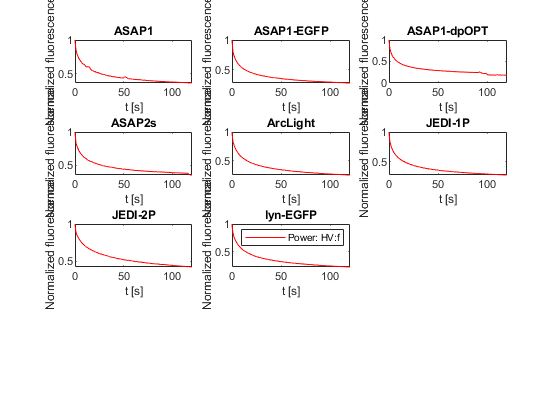

c = hsv(10);
wellGroups = findgroups(T_fovCondition.Name);
nVariants = max(wellGroups);
figure(1)
clf
for i = 1:max(wellGroups)
    T_sub = T_fovCondition(find(wellGroups ==i),:);
    subplot(4,3,i)
    hold on
    for j = 1:height(T_sub)
        plot(T_sub.TraceNorm(j).x,T_sub.TraceNorm(j).y, 'color',c(j,:));
    end
    if i == max(wellGroups)
        legend(T_sub.Settings)
    end
    xlim([0 120])
    title(T_sub.Name{1})
    xlabel('t [s]')
    ylabel('Normalized fluorescence')
    box on
end

## Plot per condition

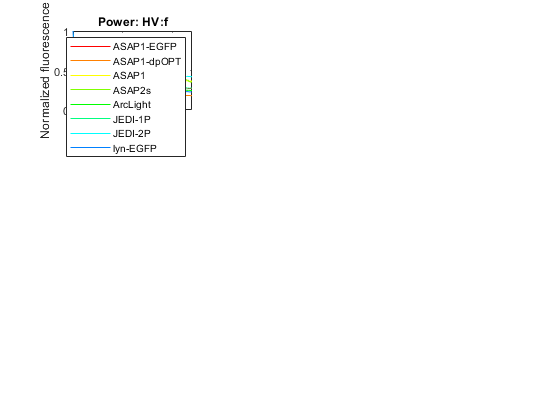

c = hsv(12);
wellGroups = findgroups(T_fovCondition.Settings);
nVariants = max(wellGroups);
figure(2)
clf
for i = 1:max(wellGroups)
    T_sub = T_fovCondition(find(wellGroups ==i),:);
    subplot(3,3,i)
    hold on
    for j = 1:height(T_sub)
        plot(T_sub.TraceNorm(j).x,T_sub.TraceNorm(j).y, 'color',c(j,:));
    end
    if i == max(wellGroups)
        legend(T_sub.Name)
    end
    xlim([0 120])
    title(T_sub.Settings{1})
    xlabel('t [s]')
    ylabel('Normalized fluorescence')
    box on
end

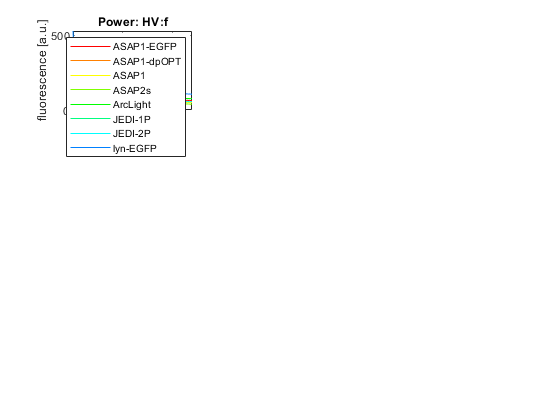

figure(3)
clf
for i = 1:max(wellGroups)
    T_sub = T_fovCondition(find(wellGroups ==i),:);
    subplot(3,3,i)
    hold on
    for j = 1:height(T_sub)
        plot(T_sub.TraceFinal(j).x,T_sub.TraceFinal(j).y,'color',c(j,:));
    end
    if i == max(wellGroups)
        legend(T_sub.Name)
    end
    xlim([0 120])
    title(T_sub.Settings{1})
    xlabel('t [s]')
    ylabel('fluorescence [a.u.]')
    box on
end

## Bar plot ranking

ans =   1×2 Bar array:

    Bar    Bar


T_sub = T_fovCondition(find(strcmp('Power:20 HV:20',T_fovCondition.Settings)),:);
libplot.formattedBar(T_sub, 'AOCNorm','AOCFinal','sort_on', 'AOCNorm', 'Name','Name','ylabel', ...
   'AUC normalized to ASAP1','norm2ctrl','ASAP1')

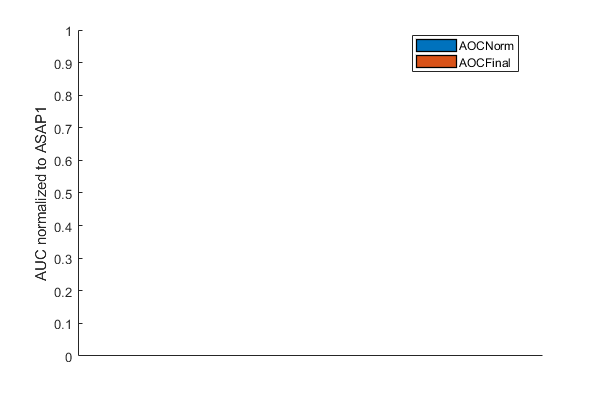

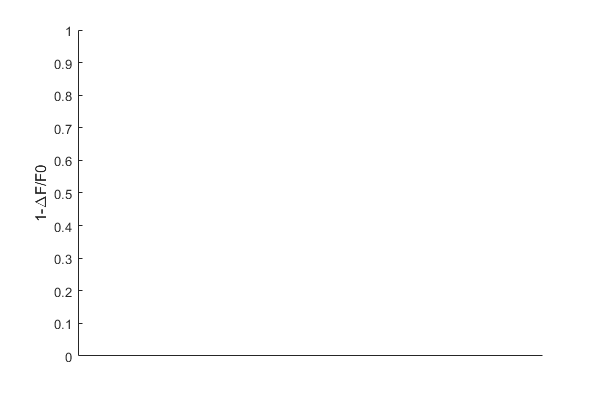

ans =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1×0 double]
        YData: [1×0 double]

  Show all properties


libplot.formattedBar(T_sub, 'RemainedRatio','sort_on', 'RemainedRatio','Name','Name','ylabel', ...
   '1-\DeltaF/F0','norm2ctrl','ASAP1')